## Association of clinically significant AR with physical exam variables

Here I want to explore the group characteristics of the cohort consisting of subjects with moderate to severe AR. One of the motivations for this investigation is to get a sense of how good cardiac auscultation is at predicting AR. Perhaps it makes more sense to investigate other ways to detect the disease, and perhaps we should not waste too much energy on trying to predict the disease based on asucultation when there are more effective ways of predicting it. First we define the dataset.

Ind = HSdata0.ARGRADE_T72>=3;
dataSick    = HSdata0(Ind,:);
dataHealthy = HSdata0(~Ind,:);

What is the **gender** **distribution** of the disease?

mean(dataSick.SEX_T7==1)

ans = 0.5563

mean(dataHealthy.SEX_T7==1)

ans = 0.4525

We see that the **males** are **overrepresented **and that Gender is **significant**. What about **age**?

mean(dataSick.AGE_T7)

ans = 71.3113

mean(dataHealthy.AGE_T7)

ans = 63.4424

As expected, AR is **associated** with **old** age, and age is **significant**. Dyspnoe, or laboured **breathing**, is an important risk factor.

mean(dataSick.DYSPNEA_FAST_UPHILL_T7==1,'omitnan')

ans = 0.4834

mean(dataHealthy.DYSPNEA_FAST_UPHILL_T7,'omitnan')

ans = 0.3829

We see that there is a significant difference of about 10%. Dyspnea is **significant**. If we use this as a test, we would have a sensitivity of 48.34% and a specificity of 61.71%. Is the "fast uphill" better at separating the two cohorts?

mean(dataSick.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0331

mean(dataHealthy.DYSPNEA_CALMLY_FLAT_T7==1,'omitnan')

ans = 0.0258

mean(dataSick.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0795

mean(dataHealthy.DYSPNOE_WASHING_DRESSING_T7==1,'omitnan')

ans = 0.0278

mean(dataSick.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0132

mean(dataHealthy.DYSPNOE_REST_T7==1,'omitnan')

ans = 0.0056

We are probably best of using the fast uphill test. Lets have a look at whether or not chest pain predicts AR.

mean(dataSick.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.1391

mean(dataHealthy.CHEST_PAIN_FAST_T7==1,'omitnan')

ans = 0.0844

it predicts it somewhat. Next let have a look at BMI. It is concievable that fat people are more likely to have AR.

mean(dataSick.BMI_T7,'omitnan')

ans = 26.3821

mean(dataHealthy.BMI_T7,'omitnan')

ans = 27.2432

BMI is actually somewhat lower for the AR cohort, but that is likely due to the fact that AR corellates strongly with age, and old people tend to be underweight. What about smoking status?

mean(dataSick.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.0993

mean(dataHealthy.SMOKE_DAILY_Q2_T7==1,'omitnan')

ans = 0.1178

actually lower prevalence of smoking amongst sick people, but not by much. What about blood pressure?

mean(dataSick.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.4834

mean(dataHealthy.HIGH_BLOOD_PRESSURE_T7>=1,'omitnan')

ans = 0.3529

And here we have our **strongest** predictor, high blood pressure. In the sick AR cohort 48.34% had high bloodpressure, whereas the healthy cohort had a 35.29% high bloodpressure. Next we look at Heart attack:

mean(dataSick.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.1258

mean(dataHealthy.HEART_ATTACK_T7>=1,'omitnan')

ans = 0.0612

No surprises there, there is higher prevalence of heart attack in the AR group. It is noteworthy however that onøy 12.6% of the AR group have had a heart attack. I thought it would be more.

mean(dataSick.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0728

mean(dataHealthy.HEART_FAILURE_T7>=1,'omitnan')

ans = 0.0303

Same conclusion as above.

mean(dataSick.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1656

mean(dataHealthy.COUGH_DAILY_T7>=1,'omitnan')

ans = 0.1668

Coughing is not a predictor of AR. 

Next lets have a look at PO2 max, which measures blood oxygen saturation, and how effective the lungs are at pulling O2 from the air.

mean(dataSick.PO2_T72,'omitnan')

ans = 97.4218

mean(dataHealthy.PO2_T72,'omitnan')  

ans = 97.6633

No difference. What about Lung capacity as measured by a spirometry?

mean(dataSick.PULSESPIRO_T72<60,'omitnan')

ans = 0.4371

mean(dataHealthy.PULSESPIRO_T72<60,'omitnan') 

ans = 0.3266

A significant group difference. The AR group had a 43.7% prevalence of scoring less than 60 on the test, whereas for the healthy group the number was only 32.7%. Finally, for good measure, we look at the predictive value of maximum murmur grade for predicting AR.

mean(dataSick.maxMeanMurGrade>=2,'omitnan')

ans = 0.2450

mean(dataHealthy.maxMeanMurGrade>=2,'omitnan') 

ans = 0.0956

risk of murmur grade >= 3 is 24.5% for the sick group, and 9.56% for the healthy group. This shows that as seemingly bad as cardiac auscultation is at predicting AR, it is still the most predictive variable amongst the variables collected during a physical examination.

### conclusions:

Age, sex, dyspnea fast upphill, high bloodpressure, chest pain, pulse spiro, and murmur grade are significant predictors of significant AR. Let us throw them all into a regression model, but first we have to see how much data is available to model.

data = HSdata0;
Inan = isnan(data.SEX_T7)+isnan(data.AGE_T7)+isnan(data.DYSPNEA_FAST_UPHILL_T7)+...
    isnan(data.HIGH_BLOOD_PRESSURE_T7) + isnan(data.PULSESPIRO_T72) +...
    isnan(data.CHEST_PAIN_FAST_T7) + isnan(data.ARGRADE_T72);
Inan = (Inan>=1);
sum(Inan)

ans = 231

we loose 231 samples.  Will exclusion of the nan entries bias our findings?

mean(data.ARGRADE_T72(~Inan)>=3)

ans = 0.0753

mean(data.ARGRADE_T72>=3)

ans = 0.0709

sum(~Inan)

ans = 1898

 We have 0.4% increase in prevalence of significant AR, which we conclude to be insiginificant source of bias. Now we **model**.

dataMdl = data(~Inan,:);
ARsig = table(dataMdl.ARGRADE_T72>=3,'VariableNames',{'ARsig'});
dataMdl = [dataMdl, ARsig];

dataMdl.SEX_T7 = categorical(dataMdl.SEX_T7);
dataMdl.DYSPNEA_FAST_UPHILL_T7 = categorical(dataMdl.DYSPNEA_FAST_UPHILL_T7);
dataMdl.HIGH_BLOOD_PRESSURE_T7 = categorical(dataMdl.HIGH_BLOOD_PRESSURE_T7>0);
dataMdl.CHEST_PAIN_FAST_T7     = categorical(dataMdl.CHEST_PAIN_FAST_T7);

formula = strcat('ARsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72')

formula = 'ARsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ARsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue  
                                   _________    _________    _______    __________

    (Intercept)                      -6.1333      0.95193    -6.4431    1.1706e-10
    AGE_T7                          0.078315     0.010738     7.2932     3.026e-13
    SEX_T7_1                         0.23328      0.18208     1.2812       0.20012
    HIGH_BLOOD_PRESSURE_T7_true      0.11727      0.18535     0.6327       0.52693
    CHEST_PAIN_FAST_T7_1             0.10103      0.28088

Get **performance curve** for prediction of significant AR:

glm.predict

ans =     0.0844
    0.0654
    0.0435
    0.0851
    0.2126
    0.0855
    0.2043
    0.1781
    0.0930
    0.0976


[X,Y,T,AUC] = perfcurve(dataMdl.ARsig, glm.predict, true)

X =          0
    0.0006
    0.0011
    0.0017
    0.0023
    0.0023
    0.0028
    0.0034
    0.0040
    0.0046


Y =          0
         0
         0
         0
         0
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070


T =     0.3836
    0.3836
    0.3518
    0.3500
    0.3485
    0.3411
    0.3375
    0.3234
    0.3142
    0.3134


AUC = 0.7442

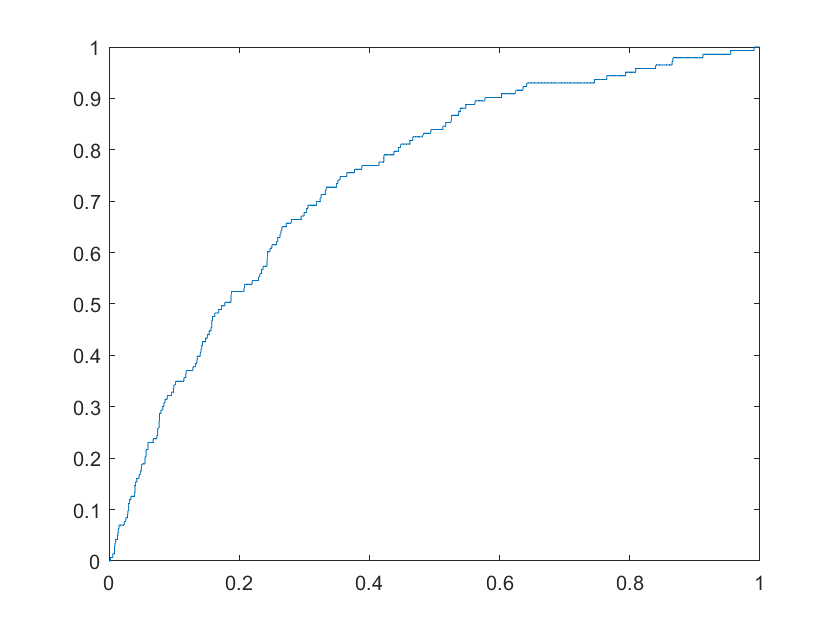

clf
plot(X,Y)

We get an AUC of **74.4% for predicting clinically significant AR**. This is surprisingly good! What happens if we model using **only** murmur grade?

[X,Y,T,AUC] = perfcurve(dataMdl.ARsig, dataMdl.Murmur_4_grade_ref_ny_T72, true)

X =          0
    0.0011
    0.0034
    0.0063
    0.0125
    0.0217
    0.0325
    0.0422
    0.0541
    0.0752


Y =          0
    0.0070
    0.0140
    0.0280
    0.0629
    0.0979
    0.1259
    0.1538
    0.1888
    0.2517


T =     4.5000
    4.5000
    4.0000
    3.5000
    3.0000
    2.5000
    2.0000
    1.5000
    1.0000
    0.5000


AUC = 0.5892

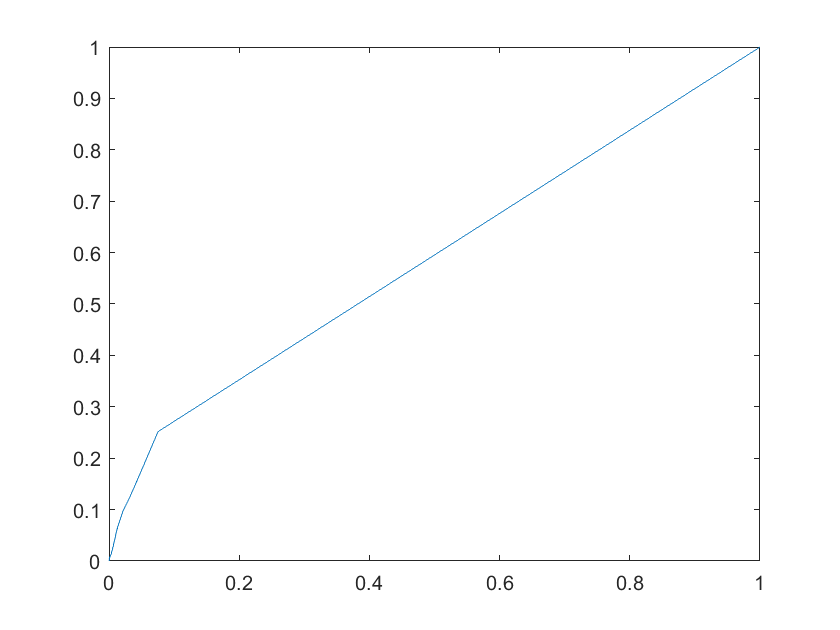

clf
plot(X,Y)

When we use only max murmur grade to predict AR, we get an AUC of **61.9%**. AUC when using recording from only one position were **59.6%**, **58.2%**, **59.6% **and  **58.9%,** so just like with AS we see that maximum murmur grade is better at predicting AR than murmur grade from only one location. This is better than I thought it would be, but not great. Cleary, using the other covariates results in a much better model. Finally, lets try adding murmur grade to the **full model.**

formula = strcat('ARsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade')

formula = 'ARsig ~ AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 +DYSPNEA_FAST_UPHILL_T7 + CHEST_PAIN_FAST_T7 + PULSESPIRO_T72 + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ARsig) ~ 1 + AGE_T7 + SEX_T7 + HIGH_BLOOD_PRESSURE_T7 + CHEST_PAIN_FAST_T7 + DYSPNEA_FAST_UPHILL_T7 + PULSESPIRO_T72 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                                   Estimate        SE         tStat       pValue  
                                   _________    _________    _______    __________

    (Intercept)                      -5.8488      0.94699    -6.1762    6.5653e-10
    AGE_T7                          0.070159     0.010873     6.4527    1.0989e-10
    SEX_T7_1                         0.29544      0.18453     1.6011       0.10936
    HIGH_BLOOD_PRESSURE_T7_true     0.040988      0.18819     0.2178       0.82758
    CHEST_PAIN_FAST_T7_1             0.


[X,Y,T,AUC] = perfcurve(dataMdl.ARsig, glm.predict, true)

X =          0
    0.0006
    0.0006
    0.0006
    0.0011
    0.0017
    0.0023
    0.0028
    0.0028
    0.0028


Y =          0
         0
    0.0070
    0.0140
    0.0140
    0.0140
    0.0140
    0.0140
    0.0210
    0.0280


T =     0.4941
    0.4941
    0.4743
    0.4361
    0.4343
    0.4252
    0.4250
    0.4243
    0.4168
    0.4156


AUC = 0.7555

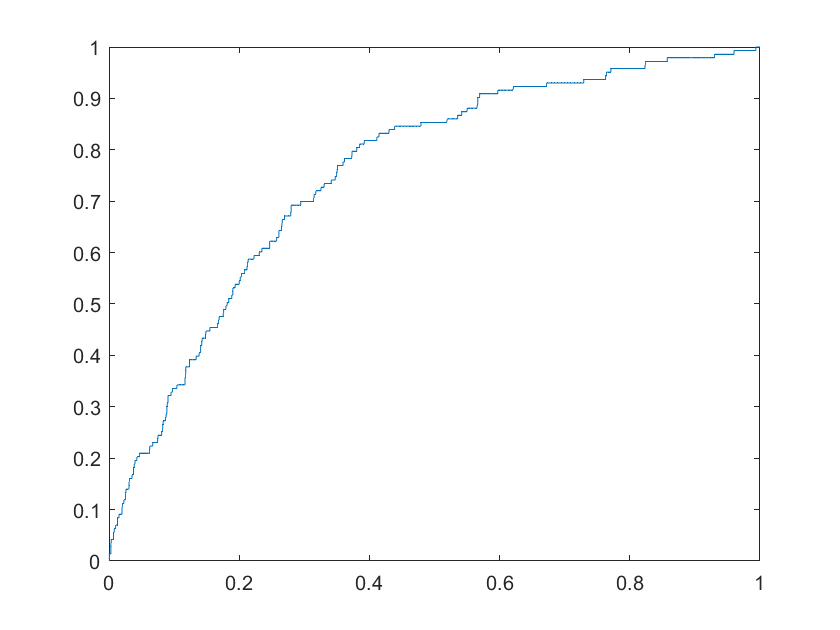

clf
plot(X,Y)

We get an AUC of **75.55%**, which is an increase of 1%. Not all that significant, but according to the fit diagnostics, murmur grade is significant. Furthermore, **blood pressure** and **chest pain** have very **insignificant p-values**, lets try **eliminating** them from the model.

formula = strcat('ARsig ~ AGE_T7 + SEX_T7 +',...
     'DYSPNEA_FAST_UPHILL_T7 + maxMeanMurGrade')

formula = 'ARsig ~ AGE_T7 + SEX_T7 +DYSPNEA_FAST_UPHILL_T7 + maxMeanMurGrade'

glm = fitglm(dataMdl,formula,'distr','binomial')

glm = Generalized linear regression model:
    logit(ARsig) ~ 1 + AGE_T7 + SEX_T7 + DYSPNEA_FAST_UPHILL_T7 + maxMeanMurGrade
    Distribution = Binomial

Estimated Coefficients:
                                Estimate       SE        tStat       pValue  
                                ________    ________    _______    __________

    (Intercept)                  -7.7934     0.74073    -10.521    6.8965e-26
    AGE_T7                      0.071704    0.010638     6.7403     1.581e-11
    SEX_T7_1                     0.39308     0.18122      2.169       0.03008
    DYSPNEA_FAST_UPHILL_T7_1     0.18429     0.18132     1.0164       0.30946
    maxMeanMurGrade              0.28503    0.073413     3.8825    0.00010337


1898 observations, 1893 error degrees of freedom
Dis


[X,Y,T,AUC] = perfcurve(dataMdl.ARsig, glm.predict, true);
AUC

AUC = 0.7392

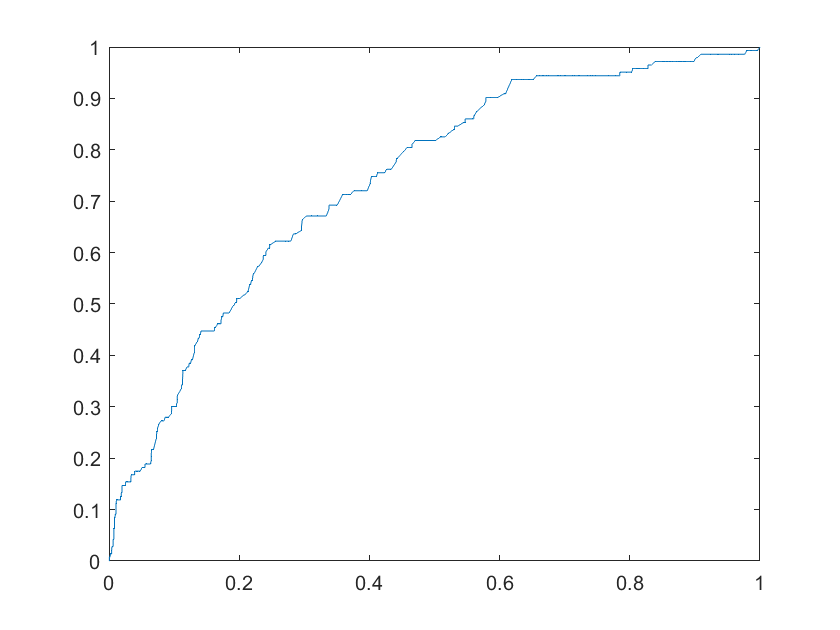

clf
plot(X,Y)

The AUC is now **75.5%. **This is actually quite promising when considering the following: 

- We have designed an algorithm that predicts which accurately predicts murmur grade, which means that all the above variables (with the possible exception of pulsespirometer) can potentially be collected easily by the patient at home in the near future.

- Studies have revealed that **undiagnosed** VHD is far more **common** than previously thought. With the implementation of the above algorithm, we could significantly increase the number of detected cases.

Together, the above points imply that implementation of the above model in combination with an implementation of  murmur detection algorithm could make available a cheap diagnostic tool the general population which offers diagnostic accuracy similar to that of a general practitioner.

Note, when we drop spirometry as a variable, the AUC is **73.9%, **which is almost as high as the full model, but requires no technology from the patient in order to perform a self checkup other than a an app on that allows them to perform computer aided murmur grade prediction at home.